依赖[统一实验分析作图v17.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

% DataSet=UniExp.DataSet("\\Data-Server-1\个人数据\张天夫\202401\全钙大模型v3.mat");

QueryTable=UniExp.ReadQueryTable("\\Data-Server-1\个人数据\张天夫\202312\统一模型查询表.xlsx","皮层分开线图");
GroupNtats=DataSet.QueryNTATS(QueryTable,UniExp.Flags.log2FdF0,1:24,UniExp.Flags.Median);

GroupNts=DataSet.QueryNTS(QueryTable,UniExp.Flags.log2FdF0,1:24);
GroupNtats=UniExp.NtatsCellReplenish(GroupNtats);
PcaTable=UniExp.LinearPca(GroupNtats.NTATS,6);

MOp

MOpNtats=MATLAB.DataTypes.Select(["NTATS","CellUID","ZLayer"],{GroupNtats,DataSet.Cells},ZLayer=["MOp2/3","MOp5"]);
[~,Index]=ismember(MOpNtats.CellUID,GroupNtats.CellUID);
MOpCoeff=PcaTable.Coeff(:,Index);

[~,MOpNtats.PeakTime]=max(MOpNtats.NTATS.Final_cue1_water(:,25:end),[],2);
sortData=sortrows(MOpNtats,"PeakTimeF1");
zeroLogical=max(sortData.NTATS.Final_cue1_water,[],2)==0&min(sortData.NTATS.Final_cue1_water,[],2)==0;
sortData=sortData(~zeroLogical,:);
intensityDataLine=mean2(sortData.NTATS.Final_cue1_water)+std2(sortData.NTATS.Final_cue1_water);

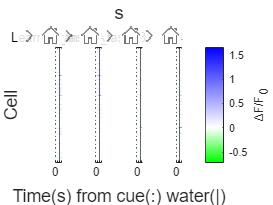

错误使用  () 
不支持使用三个或更多下标(如在 t(i,j,k) 中)对表进行索引。请始终指定一个行下标和一个变量下标，如 t(rows,vars)。

ActedCellsPeakSortHeatmap(sortData,intensityDataLine,["Learned4_cue1_water","Transfer_cue2_water","Final_cue1_water","Final_cue2_water"],["Learned_task_A","Transfer_task_B","3","4"],[0,1.5],"s","*")

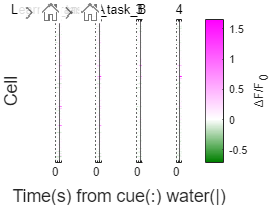

figure;
Layout=tiledlayout(1,4,TileSpacing='tight',Padding='tight');
[~,Axes]=UniExp.LanearHeatmap(sortData.NTATS(:,25:37,["Learned4_cue1_water","Transfer_cue2_water","Final_cue1_water","Final_cue2_water"]),UniExp.Flags.HideYAxis,ImagescStyle={'XData',[0,1.5]},Layout=Layout,SubTitles=["Learned_task_A","Transfer_task_B","3","4"]);
xlabel(Layout,'Time(s) from cue(:) water(|)');
ylabel(Layout,'Cell');
CB=colorbar;
CB.Layout.Tile='east';
CB.Label.String='ΔF/F_0';
for A=1:numel(Axes)
	xline(Axes(A),0,':');
	xline(Axes(A),1,'-');
end

doc print